# Task 5: The asymmetric spin-1/2 Heisenberg trimer

The asymmetric spin-1/2 Heisenberg trimer is a system of three spin-1/2 particles interacting with each other as described in the following Hamiltonian	 


$$\mathcal{H} = J_1 ({\bf S}_1 \cdot {\bf S}_2+{\bf S}_2 \cdot {\bf S}_3)+J_2 {\bf S}_3 \cdot {\bf S}_1$$


where $J_1$ and $J_2$ are real parameters (coupling constants). 

# Subtask a

Write a few lines of code that deliver the matrix representations of the operators$$S_{1x}$, $S_{1y}$, $S_{1z}$, $S_{2x}$, $S_{2y}$, $S_{2z}$, $S_{3x}$, $S_{3y}$, $S_{3z}$, $S_x\equiv S_{1x}+S_{2x}+S_{3x}$, $S_y\equiv S_{1y}+S_{2y}+S_{3y}$, $S_z\equiv S_{1z}+S_{2z}+S_{3z}$$ and $${\bf S}^2=S_x^2+S_y^2+S_z^2$$ in the `product-$$S_z$$ basis' $$\{|S_1,M_1\rangle \otimes|S_2,M_2\rangle \otimes|S_3,M_3\rangle\}$$ (or, $$\{|M_1,M_2,M_3\rangle\}$$ for simplicity).

[Sx, Sy, Sz]=FetchSpinMatrices(0.5);
S1x = kron(Sx,kron(eye(2),eye(2)))

S1x =          0         0         0         0    0.5000         0         0         0
         0         0         0         0         0    0.5000         0         0
         0         0         0         0         0         0    0.5000         0
         0         0         0         0         0         0         0    0.5000
    0.5000         0         0         0         0         0         0         0
         0    0.5000         0         0         0         0         0         0
         0         0    0.5000         0         0         0         0         0
         0         0         0    0.5000         0         0         0         0


S1y = kron(Sy,kron(eye(2),eye(2)))

S1y =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i
   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.5000i   0.0000 + 0.0000i

S1z = kron(Sz,kron(eye(2),eye(2)))

S1z =     0.5000         0         0         0         0         0         0         0
         0    0.5000         0         0         0         0         0         0
         0         0    0.5000         0         0         0         0         0
         0         0         0    0.5000         0         0         0         0
         0         0         0         0   -0.5000         0         0         0
         0         0         0         0         0   -0.5000         0         0
         0         0         0         0         0         0   -0.5000         0
         0         0         0         0         0         0         0   -0.5000


S2x = kron(eye(2),kron(Sx,eye(2)))

S2x =          0         0    0.5000         0         0         0         0         0
         0         0         0    0.5000         0         0         0         0
    0.5000         0         0         0         0         0         0         0
         0    0.5000         0         0         0         0         0         0
         0         0         0         0         0         0    0.5000         0
         0         0         0         0         0         0         0    0.5000
         0         0         0         0    0.5000         0         0         0
         0         0         0         0         0    0.5000         0         0


S2y = kron(eye(2),kron(Sy,eye(2)))

S2y =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i

S2z = kron(eye(2),kron(Sz,eye(2)))

S2z =     0.5000         0         0         0         0         0         0         0
         0    0.5000         0         0         0         0         0         0
         0         0   -0.5000         0         0         0         0         0
         0         0         0   -0.5000         0         0         0         0
         0         0         0         0    0.5000         0         0         0
         0         0         0         0         0    0.5000         0         0
         0         0         0         0         0         0   -0.5000         0
         0         0         0         0         0         0         0   -0.5000


S3x = kron(eye(2),kron(eye(2),Sx))

S3x =          0    0.5000         0         0         0         0         0         0
    0.5000         0         0         0         0         0         0         0
         0         0         0    0.5000         0         0         0         0
         0         0    0.5000         0         0         0         0         0
         0         0         0         0         0    0.5000         0         0
         0         0         0         0    0.5000         0         0         0
         0         0         0         0         0         0         0    0.5000
         0         0         0         0         0         0    0.5000         0


S3y = kron(eye(2),kron(eye(2),Sy))

S3y =    0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i

S3z = kron(eye(2),kron(eye(2),Sz))

S3z =     0.5000         0         0         0         0         0         0         0
         0   -0.5000         0         0         0         0         0         0
         0         0    0.5000         0         0         0         0         0
         0         0         0   -0.5000         0         0         0         0
         0         0         0         0    0.5000         0         0         0
         0         0         0         0         0   -0.5000         0         0
         0         0         0         0         0         0    0.5000         0
         0         0         0         0         0         0         0   -0.5000


Sx = S1x + S2x + S3x

Sx =          0    0.5000    0.5000         0    0.5000         0         0         0
    0.5000         0         0    0.5000         0    0.5000         0         0
    0.5000         0         0    0.5000         0         0    0.5000         0
         0    0.5000    0.5000         0         0         0         0    0.5000
    0.5000         0         0         0         0    0.5000    0.5000         0
         0    0.5000         0         0    0.5000         0         0    0.5000
         0         0    0.5000         0    0.5000         0         0    0.5000
         0         0         0    0.5000         0    0.5000    0.5000         0


Sy = S1y + S2y + S3y

Sy =    0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.5000i   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i
   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 - 0.5000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.5000i   0.0000 + 0.0000i 

Sz = S1z + S2z + S3z

Sz =     1.5000         0         0         0         0         0         0         0
         0    0.5000         0         0         0         0         0         0
         0         0    0.5000         0         0         0         0         0
         0         0         0   -0.5000         0         0         0         0
         0         0         0         0    0.5000         0         0         0
         0         0         0         0         0   -0.5000         0         0
         0         0         0         0         0         0   -0.5000         0
         0         0         0         0         0         0         0   -1.5000


Ssquared = Sx*Sx + Sy*Sy + Sz*Sz

Ssquared =     3.7500         0         0         0         0         0         0         0
         0    1.7500    1.0000         0    1.0000         0         0         0
         0    1.0000    1.7500         0    1.0000         0         0         0
         0         0         0    1.7500         0    1.0000    1.0000         0
         0    1.0000    1.0000         0    1.7500         0         0         0
         0         0         0    1.0000         0    1.7500    1.0000         0
         0         0         0    1.0000         0    1.0000    1.7500         0
         0         0         0         0         0         0         0    3.7500


# Subtask b			

Write a few lines of code that deliver the matrix representation of $\mathcal{H}$for $J_1 = 1$ and $J_2 = 0.25$. Solve the Schroedinger equation (eigenvalue matrix equation) to obtain the energy eigenvalues and the corresponding eigenstates of $\mathcal{H}$. 

J1 = 1

J1 = 1

J2 = 0.25

J2 = 0.2500

Hamiltonian = J1*((S1x*S2x + S1y*S2y + S1z*S2z)+(S2x*S3x + S2y*S3y + S2z*S3z)) + J2*(S3x*S1x + S3y*S1y + S3z*S1z)

Hamiltonian =     0.5625         0         0         0         0         0         0         0
         0   -0.0625    0.5000         0    0.1250         0         0         0
         0    0.5000   -0.4375         0    0.5000         0         0         0
         0         0         0   -0.0625         0    0.5000    0.1250         0
         0    0.1250    0.5000         0   -0.0625         0         0         0
         0         0         0    0.5000         0   -0.4375    0.5000         0
         0         0         0    0.1250         0    0.5000   -0.0625         0
         0         0         0         0         0         0         0    0.5625


Energy = eig(Hamiltonian);
[V,D] = eig(Hamiltonian)

V =          0         0         0         0    1.0000         0         0         0
   -0.4082         0   -0.7071         0         0         0         0   -0.5774
    0.8165         0    0.0000         0         0         0         0   -0.5774
         0   -0.4082         0   -0.7071         0         0   -0.5774         0
   -0.4082         0    0.7071         0         0         0         0   -0.5774
         0    0.8165         0    0.0000         0         0   -0.5774         0
         0   -0.4082         0    0.7071         0         0   -0.5774         0
         0         0         0         0         0    1.0000         0         0


D =    -0.9375         0         0         0         0         0         0         0
         0   -0.9375         0         0         0         0         0         0
         0         0   -0.1875         0         0         0         0         0
         0         0         0   -0.1875         0         0         0         0
         0         0         0         0    0.5625         0         0         0
         0         0         0         0         0    0.5625         0         0
         0         0         0         0         0         0    0.5625         0
         0         0         0         0         0         0         0    0.5625


EigState1 = V(:,1)

EigState1 =          0
   -0.4082
    0.8165
         0
   -0.4082
         0
         0
         0


Energy1 = Energy(1)

Energy1 = -0.9375

EigState2 = V(:,2)

EigState2 =          0
         0
         0
   -0.4082
         0
    0.8165
   -0.4082
         0


Energy2 = Energy(2)

Energy2 = -0.9375

EigState3 = V(:,3)

EigState3 =          0
   -0.7071
    0.0000
         0
    0.7071
         0
         0
         0


Energy3 = Energy(3)

Energy3 = -0.1875

EigState4 = V(:,4)

EigState4 =          0
         0
         0
   -0.7071
         0
    0.0000
    0.7071
         0


Energy4 = Energy(4)

Energy4 = -0.1875

EigState5 = V(:,5)

EigState5 =      1
     0
     0
     0
     0
     0
     0
     0


Energy5 = Energy(5)

Energy5 = 0.5625

EigState6 = V(:,6)

EigState6 =      0
     0
     0
     0
     0
     0
     0
     1


Energy6 = Energy(6)

Energy6 = 0.5625

EigState7 = V(:,7)

EigState7 =          0
         0
         0
   -0.5774
         0
   -0.5774
   -0.5774
         0


Energy7 = Energy(7)

Energy7 = 0.5625

EigState8 = V(:,8)

EigState8 =          0
   -0.5774
   -0.5774
         0
   -0.5774
         0
         0
         0


Energy8 = Energy(8)

Energy8 = 0.5625

# Subtask c

Calculate the commutator $[\mathcal{H},{\bf S}^2]$ and then check explicitly that each eigenstate of $\mathcal{H}$ is also an eigenstate of the operator ${\bf S}^2$. The corresponding eigenvalues are given by $S(S+1)$, where $S$ is the 'total spin quantum number'. What is value of $S$ for each eigenstate of $\mathcal{H}$?

HamiltonianCommutatorSsquared = (Hamiltonian * Ssquared - Ssquared * Hamiltonian)

HamiltonianCommutatorSsquared =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


Ssquared * EigState1

ans =          0
   -0.3062
    0.6124
         0
   -0.3062
         0
         0
         0


Ssquared * EigState2

ans =          0
         0
         0
   -0.3062
         0
    0.6124
   -0.3062
         0


Ssquared * EigState3

ans =          0
   -0.5303
    0.0000
         0
    0.5303
         0
         0
         0


Ssquared * EigState4

ans =          0
         0
         0
   -0.5303
         0
    0.0000
    0.5303
         0


Ssquared * EigState5

ans =     3.7500
         0
         0
         0
         0
         0
         0
         0


Ssquared * EigState6

ans =          0
         0
         0
         0
         0
         0
         0
    3.7500


Ssquared * EigState7

ans =          0
         0
         0
   -2.1651
         0
   -2.1651
   -2.1651
         0


Ssquared * EigState8

ans =          0
   -2.1651
   -2.1651
         0
   -2.1651
         0
         0
         0


(Ssquared * EigState1) ./ EigState1

ans =        NaN
    0.7500
    0.7500
       NaN
    0.7500
       NaN
       NaN
       NaN


(Ssquared * EigState2) ./ EigState2

ans =        NaN
       NaN
       NaN
    0.7500
       NaN
    0.7500
    0.7500
       NaN


round(Ssquared * EigState3,10) ./ round(EigState3,10)

ans =        NaN
    0.7500
       NaN
       NaN
    0.7500
       NaN
       NaN
       NaN


round(Ssquared * EigState4,10) ./ round(EigState4,10)

ans =        NaN
       NaN
       NaN
    0.7500
       NaN
       NaN
    0.7500
       NaN


(Ssquared * EigState5) ./ EigState5

ans =     3.7500
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


(Ssquared * EigState6) ./ EigState6

ans =        NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
    3.7500


(Ssquared * EigState7) ./ EigState7

ans =        NaN
       NaN
       NaN
    3.7500
       NaN
    3.7500
    3.7500
       NaN


(Ssquared * EigState8) ./ EigState8

ans =        NaN
    3.7500
    3.7500
       NaN
    3.7500
       NaN
       NaN
       NaN


%Eigenvalues = 0.75, 0.75, 0.75, 0.75, 3.75, 3.75, 3.75, 3.75
%Where Evals = 0.75, Total quantum spin number = 0.5 (or -1.5)
%Wherre evals = 3.75, Total quantum spin number = 1.5 (or -2.5)
%Using the round function as computer has rounding errors where values that
%should be 0 are slightly above.

# Subtask d					

We now fix $J_1 = 1$ and consider a variable $J_2$. Plot the energy spectrum vs $J_2/J_1$, in the range $J_2/J_1 \in [-5,5]$.

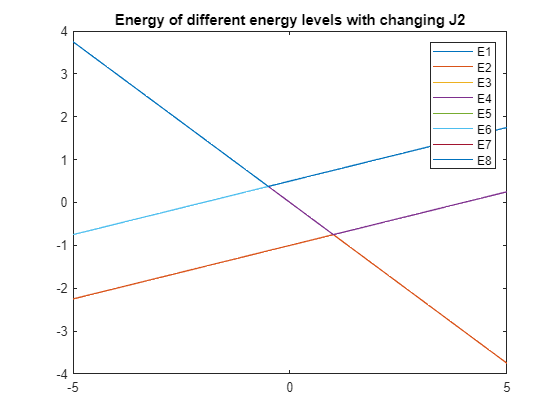

%add your code here
E1 = [];
E2 = [];
E3 = [];
E4 = [];
E5 = [];
E6 = [];
E7 = [];
E8 = [];

for J2 = -5:0.1:5;
    Hamiltonian = J1*((S1x*S2x + S1y*S2y + S1z*S2z)+(S2x*S3x + S2y*S3y + S2z*S3z)) + J2*(S3x*S1x + S3y*S1y + S3z*S1z);
    Energy = eig(Hamiltonian);
    E1 = [E1 Energy(1)];
    E2 = [E2 Energy(2)];
    E3 = [E3 Energy(3)];
    E4 = [E4 Energy(4)];
    E5 = [E5 Energy(5)];
    E6 = [E6 Energy(6)];
    E7 = [E7 Energy(7)];
    E8 = [E8 Energy(8)];
end;
y = -5:0.1:5;
plot(y,E1)
hold on
plot(y,E2)
hold on
plot(y,E3)
hold on
plot(y,E4)
hold on
plot(y,E5)
hold on
plot(y,E6)
hold on
plot(y,E7)
hold on
plot(y,E8)
hold on
legend('E1','E2','E3','E4','E5','E6','E7','E8')
title("Energy of different energy levels with changing J2")
hold off

# Subtask e

Plot the $\textbf{ground state}$ expectation value of the operator ${\bf S}^2$ vs $J_2/J_1$, in the range $J_2/J_1 \in [-5,5]$.

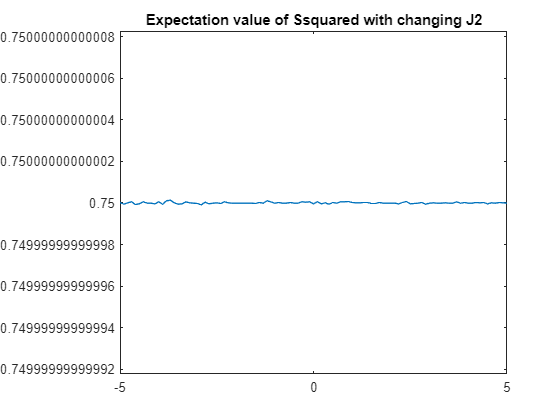

ExpectationSsquared = [];
for J2 = -5:0.1:5;
     Hamiltonian = J1*((S1x*S2x + S1y*S2y + S1z*S2z)+(S2x*S3x + S2y*S3y + S2z*S3z)) + J2*(S3x*S1x + S3y*S1y + S3z*S1z);
    [V,D] = eig(Hamiltonian);
    EigState1 = V(:,1);
    E1ExpectationSsquared = EigState1' * Ssquared * EigState1;
    ExpectationSsquared = [ExpectationSsquared E1ExpectationSsquared];
end
ExpectationSsquared;
x = -5:0.1:5;
plot(x,ExpectationSsquared)
title("Expectation value of Ssquared with changing J2")

Function for finding spin matracies as provided

function [Sx, Sy, Sz, Sp, Sm]=FetchSpinMatrices(S)

%sanity check
if rem(2*S,1)~=0; 
 disp('please provide an integer or half-integer value for S'); 
 return; 
end

dim=2*S+1; %dimension of Hilbert space

%initialize the matrices
Sx=zeros(dim,dim); Sy=zeros(dim,dim); Sz=zeros(dim,dim); Sp=zeros(dim,dim); Sm=zeros(dim,dim);


j=0;
for m=S:-1:-S; j=j+1;

 %Sz matrix
 Sz(j,j)=m;

 %Sp matrix
 f1=sqrt(S*(S+1)-m*(m+1));
 if f1~=0; 
  Sp(j-1,j)=f1; %matrix element between the bra <m+1| (corresponding to index j-1) and ket |m> (corresponding to index j)
 end

 %Sm matrix
 f2=sqrt(S*(S+1)-m*(m-1));
 if f2~=0; 
  Sm(j+1,j)=f2; %matrix element between the bra <m-1| (corresponding to index j+1) and ket |m> (corresponding to index j)
 end

end
Sx=(Sp+Sm)/2;
Sy=(Sp-Sm)/(2*complex(0,1));

return
end